%Load signal in matlab
figure;
load openloop60hertz,openLoop= openLoopVoltage;
Fs=1000

Fs = 1000

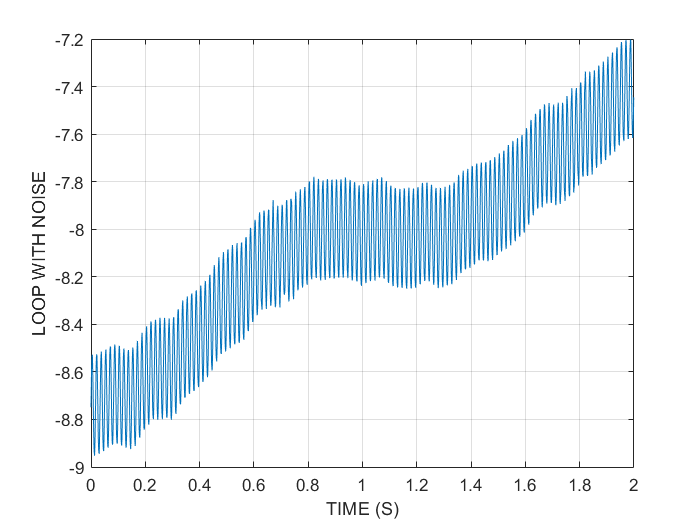

t=(0:length(openLoop)-1)/Fs;
plot(t,openLoop);box on;grid on;
ylabel('LOOP WITH NOISE')
xlabel('TIME (S)')

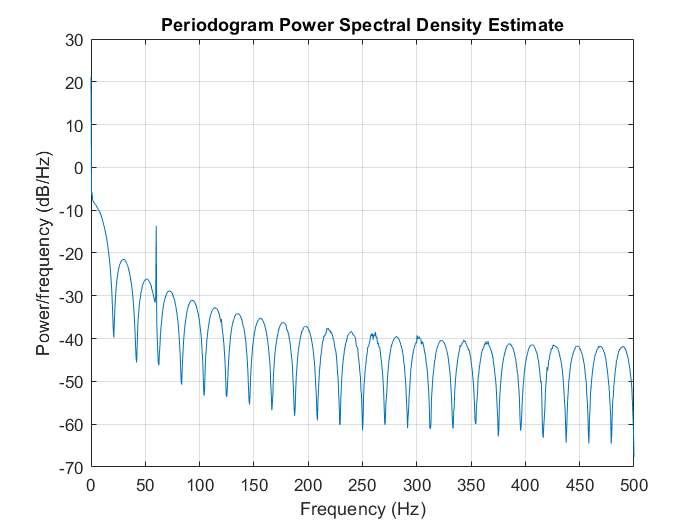



%Power Spectrum
figure;
periodogram(openLoop,[],[],Fs);

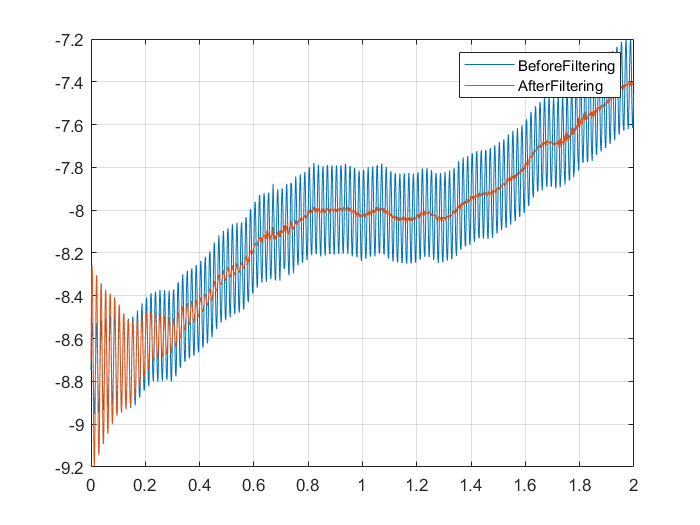



%Design of BandStop filter

filtCoeff =designfilt('bandstopiir','Filterorder',2,'HalfPowerFrequency1',59,'HalfpowerFrequency2',61,'Samplerate',Fs);
%visulaize the filter
fvtool(filtCoeff);

noiseFreeSignal=filter(filtCoeff,openLoop);
%Verify the result in time domain
close all;
figure;
plot(t,openLoop,t,noiseFreeSignal);
grid on;
legend('BeforeFiltering','AfterFiltering');



%compenstate for constant delay 
%Load signals
load FIRDelay.mat

Error using load
Unable to read file 'FIRDelay.mat'. No such file or directory.

plot(tn,xn);
hold on,
plot(tn,xf,'-r','linewidth',1.5), 
hold off 
xlabel 'Time (s)' ,legend ('Original Signal','Filtred SIgnal')
box on;
grid on;
%Visualize delay 
grpdelay(d,N,500)
delay=mean(grpdelay(d))
